# HMM Analysis

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

Figflag = 0;

## Part 1: Add working path and load the data

We will initialize the paths that are used later

Prefix_3 = 'optoknirps_new_embryo7';
Prefix_4 = 'optoknirps_new_embryo10';

% Make figure path
FigPath = ['./figure/'];
mkdir(FigPath)

mkdir([FigPath, Prefix_3,'/'])

mkdir([FigPath, Prefix_4,'/'])

Now, load all the data

load('./data/hmm_input_output.mat')

Specify some parameters

numParticle = length(hmm_input_output);
APbinID = linspace(0,100,101); % AP bin for calculation

TimeOffset_3 = 15.82;
TimeSwitch_3 = 18.64;

TimeOffset_4 = 2.5;
TimeSwitch_4 = 20.3;

% Specify the bins we are interested in
binRange_3 = 63:65; % min:63 max:65 confirmed
binRange_4 = 61:65; % 60%-64%

## Part 2: Fliter traces including quality control

We can assign the traces to each AP bin

APPosition_mean = zeros(numParticle,1);

for i = 1:numParticle
    APPosition_mean(i) = mean(hmm_input_output(i).APPosition);
end

APbinData = discretize(APPosition_mean,APbinID);

Quality control: Only keep the traces that is continuous across specified time range

QualityFlag = zeros(numParticle,1);

LeftBound = 15;
RightBound = 25;

for i = 1:numParticle
    
    MinTime = hmm_input_output(i).Time(1)/60;
    MaxTime = hmm_input_output(i).Time(end)/60;
    
    if hmm_input_output(i).SetID == 4
        MinTime = hmm_input_output(i).Time(1)/60-TimeOffset_4;
        MaxTime = hmm_input_output(i).Time(end)/60-TimeOffset_4;
    end

    if hmm_input_output(i).SetID == 3
        MinTime = hmm_input_output(i).Time(1)/60-TimeOffset_3;
        MaxTime = hmm_input_output(i).Time(end)/60-TimeOffset_3;
    end

    if (MinTime<LeftBound) && (MaxTime>RightBound)
        QualityFlag(i) = 1;
    else
        QualityFlag(i) = 0;
    end
end

We want to filter the traces based on SetID

SetID_all = [hmm_input_output(:).SetID]; % SetID for all the traces    

## Part 3: Plot traces

### No Export -> Export

Let's plot some traces

dataID = 4; % We want to analyze "optoknirps_new_embryo10"

SpotTime = hmm_input_output(1).Time;

TraceIndex_4 = find((SetID_all == dataID) & (ismember(APbinData,binRange_4)') & QualityFlag');

for i = TraceIndex_4
    ParticleID = hmm_input_output(i).ParticleID;
    SpotTime = hmm_input_output(i).Time/60-TimeOffset_4; % convert to min
    
    if Figflag
        p = i;
        fluo_fig = figure;
        hold on
        plot(SpotTime,hmm_input_output(p).SpotFluorescence,'LineWidth',1.5)
        plot(SpotTime,hmm_input_output(p).FluoViterbi,'--','LineWidth',1.5)
        ylabel('spot fluorescence (au)')
        ylim([0 3E5])
        
        yyaxis right
        plot(SpotTime,hmm_input_output(p).NuclearKnirps,'-','Color','g','LineWidth',1.5)
        ylim([0 8E5])
        ylabel('knirps level (au)')
        
        xlabel('time into nc14 (min)')
        xlim([0 40])
        set(gca,'Fontsize',14)
        
        saveas(fluo_fig,[FigPath, Prefix_4, '/', 'particle' num2str(ParticleID) '_fluo_plot.png'])
        
        v_fig = figure;
        hold on
        plot(SpotTime,hmm_input_output(p).InitiationRate,'LineWidth',1.5)
        stairs(SpotTime,hmm_input_output(p).PromoterState,'-','LineWidth',1.5)
        ylim([0 3E3])
        
        ylabel('initiation rate')
        yyaxis right
        plot(SpotTime,hmm_input_output(p).NuclearKnirps,'-','Color','g','LineWidth',1.5)
        ylim([0 8E5])
        ylabel('knirps level (au)')
        
        xlabel('time into nc14 (min)')
        xlim([0 40])
        set(gca,'Fontsize',14)
        
        saveas(v_fig,[FigPath, Prefix_4, '/', 'particle' num2str(ParticleID) '_v_plot.png'])
    end
end

### Export -> No export

dataID = 3; % We want to analyze "optoknirps_new_embryo7"
Prefix = 'optoknirps_new_embryo7';

TraceIndex_3 = find((SetID_all == dataID) & (ismember(APbinData,binRange_3)') & QualityFlag');

for i = TraceIndex_3
    ParticleID = hmm_input_output(i).ParticleID;
    SpotTime = hmm_input_output(i).Time/60-TimeOffset_3; % convert to min
   
    if Figflag
        p = i;
        fluo_fig = figure;
        hold on
        plot(SpotTime,hmm_input_output(p).SpotFluorescence,'LineWidth',1.5)
        plot(SpotTime,hmm_input_output(p).FluoViterbi,'--','LineWidth',1.5)
        ylabel('spot fluorescence (au)')
        ylim([0 3E5])
        
        yyaxis right
        plot(SpotTime,hmm_input_output(p).NuclearKnirps,'-','Color','g','LineWidth',1.5)
        ylim([0 1.2E6])
        ylabel('knirps level (au)')
        
        xlabel('time into nc14 (min)')
        xlim([0 40])
        set(gca,'Fontsize',14)
        
        saveas(fluo_fig,[FigPath, Prefix_3, '/', 'particle' num2str(ParticleID) '_fluo_plot.png'])
        
        v_fig = figure;
        hold on
        plot(SpotTime,hmm_input_output(p).InitiationRate,'LineWidth',1.5)
        stairs(SpotTime,hmm_input_output(p).PromoterState,'-','LineWidth',1.5)
        ylim([0 3E3])
        
        ylabel('initiation rate')
        yyaxis right
        plot(SpotTime,hmm_input_output(p).NuclearKnirps,'-','Color','g','LineWidth',1.5)
        ylim([0 1.2E6])
        ylabel('knirps level (au)')
        
        xlabel('time into nc14 (min)')
        xlim([0 40])
        set(gca,'Fontsize',14)
        
        saveas(v_fig,[FigPath, Prefix_3,'/','particle' num2str(ParticleID) '_v_plot.png'])
    end
end

## Part 4: Waiting-time distribution for purturbed region

We can use this to calculate response time

### No export -> Export

dataID = 4;
TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange_4)') & QualityFlag');

TimeOn = [];

for i = TraceIndex
    SpotTime = hmm_input_output(i).Time/60-TimeOffset_4; % convert to min
    PromState = hmm_input_output(i).PromoterState;
    [val,idx]=min(abs(SpotTime-TimeSwitch_4));
    
    if (PromState(idx) <10) && (val<2)
        temp_state = PromState(idx:end);
        temp_time = SpotTime(idx:end);
        frame_on = find(temp_state > 10, 1);
        time_first_on = temp_time(frame_on)-temp_time(1);
        TimeOn = [TimeOn time_first_on];
    end
end


Plot the distribution and exponential fitting

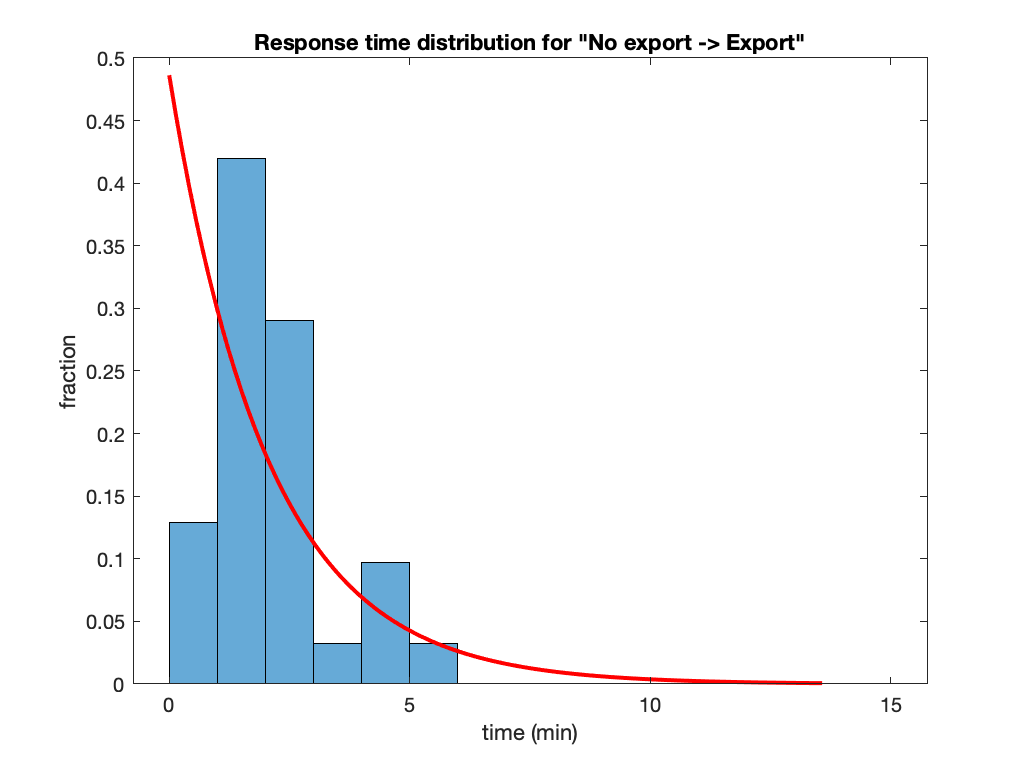

timeFigure = figure;
data = TimeOn;
dist = 'exponential';
pd = fitdist(data',dist);
% Find range for plotting
q = icdf(pd,[0.0013499 0.99865]); % three-sigma range for normal distribution
x = linspace(q(1),q(2));

% Do histogram calculations
edges = linspace(0,15,16);
h = histogram(data,edges,'Normalization','probability');
hold on
% Find range for plotting
q = icdf(pd,[0.0013499 0.99865]); % three-sigma range for normal distribution
x = linspace(q(1),q(2));

% Normalize the density to match the total area of the histogram
n = numel(data);
binwidth = edges(2)-edges(1); % Finds the width of each bin
area = n * binwidth;
y = area * pdf(pd,x);

% Overlay the density
hh1 = plot(x,y/n,'r-','LineWidth',2);

title('Response time distribution for "No export -> Export"')
%histogram(TimeOn)
%histfit(TimeOn,5,'exponential')
xlabel('time (min)')
ylabel('fraction')

mean(data)

ans = 2.0538

SEM = std(data)/sqrt(length(data))

SEM = 0.2246

### Export -> No export

dataID = 3;
TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange_3)') & QualityFlag');

TimeOn = [];

for i = TraceIndex
    SpotTime = hmm_input_output(i).Time/60-TimeOffset_3; % convert to min
    PromState = hmm_input_output(i).PromoterState;
    [val,idx]=min(abs(SpotTime-TimeSwitch_3));
    
    if (PromState(idx) >10) && (val<2)
        temp_state = PromState(idx:end);
        temp_time = SpotTime(idx:end);
        frame_on = find(temp_state < 10, 1);
        time_first_on = temp_time(frame_on)-temp_time(1);
        TimeOn = [TimeOn time_first_on];
    end
end


Plot the distribution and exponential fitting

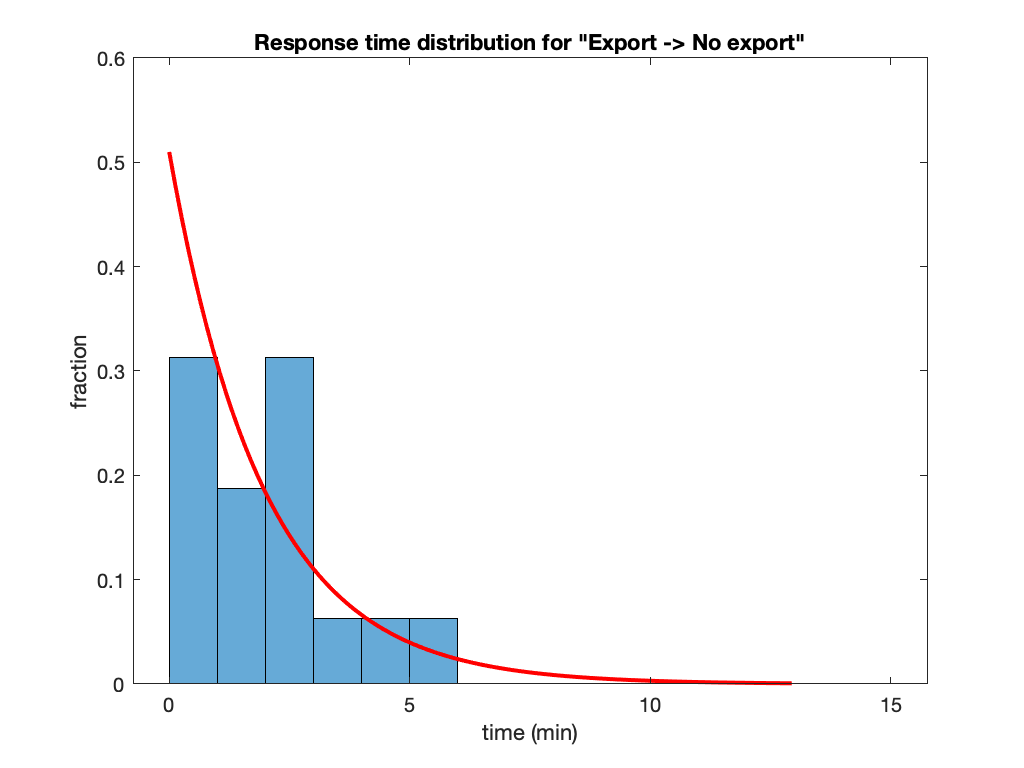

timeFigure = figure;
data = TimeOn;
dist = 'exponential';
pd = fitdist(data',dist);
% Find range for plotting
q = icdf(pd,[0.0013499 0.99865]); % three-sigma range for normal distribution
x = linspace(q(1),q(2));

% Do histogram calculations
edges = linspace(0,15,16);
h = histogram(data,edges,'Normalization','probability');
hold on
% Find range for plotting
q = icdf(pd,[0.0013499 0.99865]); % three-sigma range for normal distribution
x = linspace(q(1),q(2));

% Normalize the density to match the total area of the histogram
n = numel(data);
binwidth = edges(2)-edges(1); % Finds the width of each bin
area = n * binwidth;
y = area * pdf(pd,x);

% Overlay the density
hh1 = plot(x,y/n,'r-','LineWidth',2);

title('Response time distribution for "Export -> No export"')
%histogram(TimeOn)
%histfit(TimeOn,5,'exponential')
xlabel('time (min)')
ylabel('fraction')

mean(data)

ans = 1.9583

SEM = std(data)/sqrt(length(data))

SEM = 0.3560

## Waiting time distribution for other time points (control)

### Waiting time distribution for on -> off (embryo 10, at 10 min)

Quality control: We need to redo quality control since we care about traces at other timepoints

QualityFlag_others = zeros(numParticle,1);

LeftBound = 2.5;
RightBound = 15;

for i = 1:numParticle
    MinTime = hmm_input_output(i).Time(1)/60-TimeOffset_4;
    MaxTime = hmm_input_output(i).Time(end)/60-TimeOffset_4;

    if (MinTime<LeftBound) && (MaxTime>RightBound)
        QualityFlag_others(i) = 1;
    else
        QualityFlag_others(i) = 0;
    end
end

### Calculating waiting time distribution

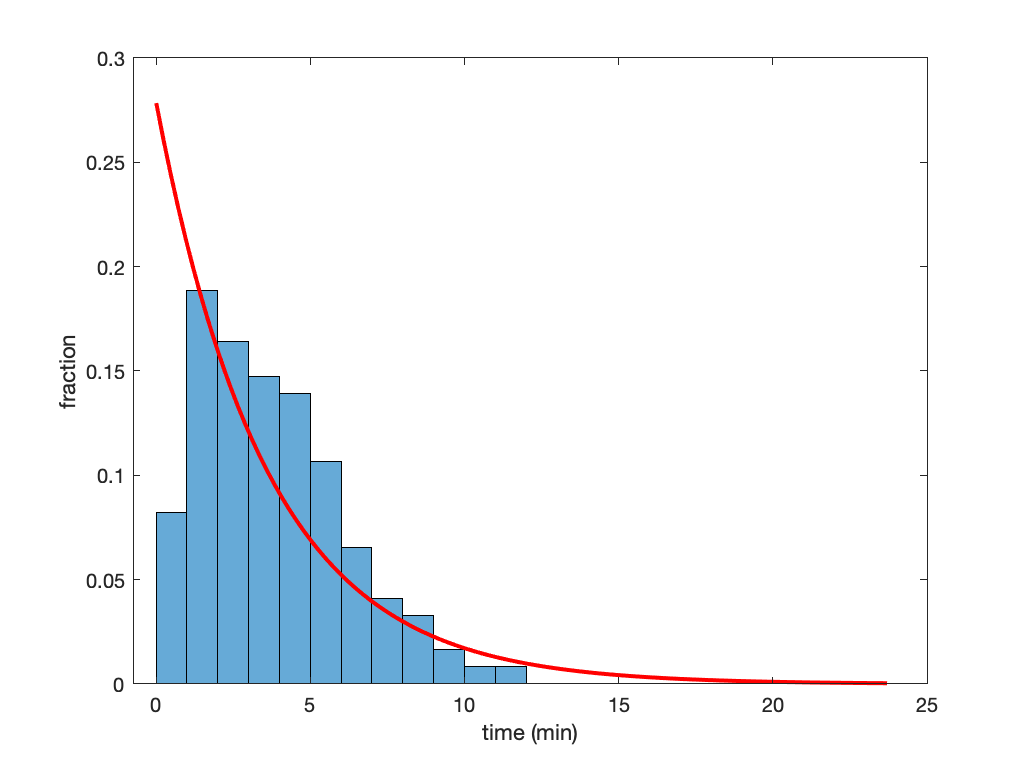

dataID = 4;

%TestTime = [5,10]; % min
%TestTime = [7.5,10,12.5]; % min
TestTime = [7,8,9,10,11,12];
%TestTime = 10;

% Specify the bins we want to plot
binRange = 61:65;
TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)') & QualityFlag_others');

WaitingTime = [];

for i = TraceIndex
    for j = 1:length(TestTime)
        SpotTime = hmm_input_output(i).Time/60-TimeOffset_4; % convert to min
        PromState = hmm_input_output(i).PromoterState;
        [val,idx]=min(abs(SpotTime-TestTime(j)));
        
        if (PromState(idx) >10) && (val<1)
            temp_state = PromState(idx:end);
            temp_time = SpotTime(idx:end);
            frame_on = find(temp_state < 10, 1);
            time_first_on = temp_time(frame_on)-temp_time(1);
            WaitingTime = [WaitingTime time_first_on];
        end
    end
end

timeFigure = figure;

data = WaitingTime;
dist = 'exponential';
pd = fitdist(data',dist);
% Find range for plotting
q = icdf(pd,[0.0013499 0.99865]); % three-sigma range for normal distribution
x = linspace(q(1),q(2));

% Do histogram calculations
edges = linspace(0,15,16);
h = histogram(data,edges,'Normalization','probability');
hold on
% Find range for plotting
q = icdf(pd,[0.0013499 0.99865]); % three-sigma range for normal distribution
x = linspace(q(1),q(2));

% Normalize the density to match the total area of the histogram
n = numel(data);
binwidth = edges(2)-edges(1); % Finds the width of each bin
area = n * binwidth;
y = area * pdf(pd,x);

% Overlay the density
hh1 = plot(x,y/n,'r-','LineWidth',2);

%histogram(TimeOn)
%histfit(TimeOn,5,'exponential')
xlabel('time (min)')
ylabel('fraction')

mean(data)

ans = 3.5874

SEM = std(data)/sqrt(length(data))

SEM = 0.2229

### Waiting time distribution for on -> off (embryo 7, at 10 min)

Quality control: We need to redo quality control since we care about traces at other timepoints

QualityFlag_others = zeros(numParticle,1);

LeftBound = 5;
RightBound = 15;

for i = 1:numParticle
    MinTime = hmm_input_output(i).Time(1)/60-TimeOffset_3;
    MaxTime = hmm_input_output(i).Time(end)/60-TimeOffset_3;

    if (MinTime<LeftBound) && (MaxTime>RightBound)
        QualityFlag_others(i) = 1;
    else
        QualityFlag_others(i) = 0;
    end
end

### Calculating waiting time distribution

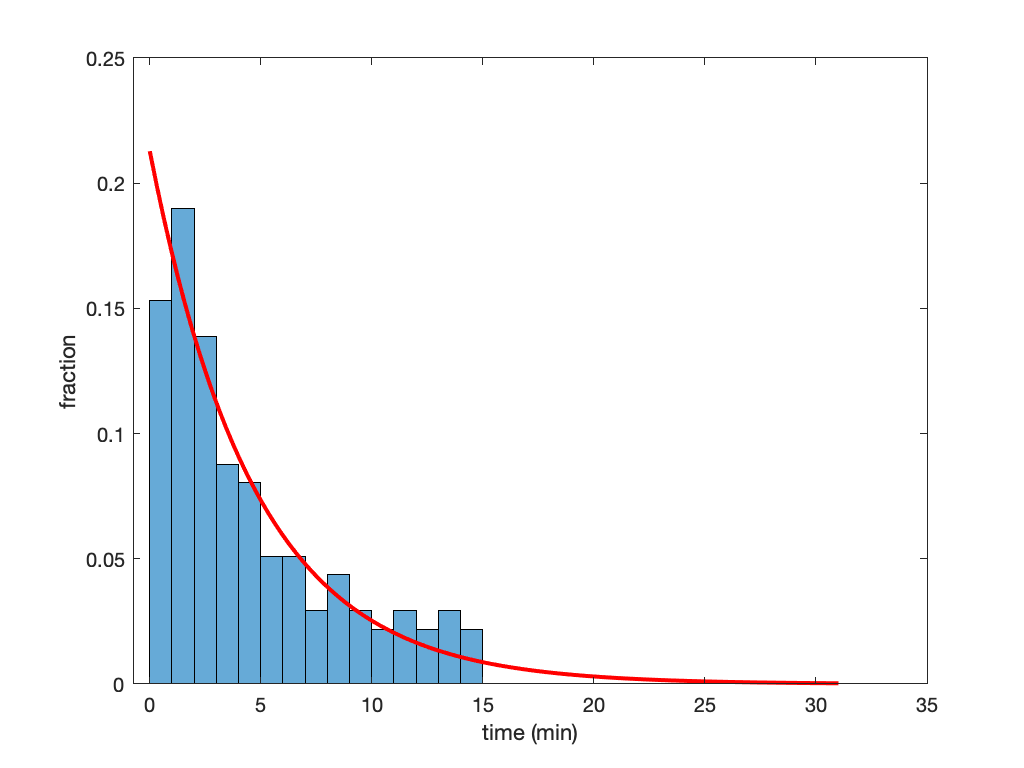

dataID = 3;

% Specify the bins we want to plot
binRange = 61:65;

%TestTime = 10; % min
TestTime = [5,6,7,8,9,10];

TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)') & QualityFlag_others');
WaitingTime = [];

for i = TraceIndex
    for j = 1:length(TestTime)
        SpotTime = hmm_input_output(i).Time/60-TimeOffset_3; % convert to min
        PromState = hmm_input_output(i).PromoterState;
        [val,idx]=min(abs(SpotTime-TestTime(j)));
        
        if (PromState(idx) > 10) && (val<1)
            temp_state = PromState(idx:end);
            temp_time = SpotTime(idx:end);
            frame_on = find(temp_state < 10, 1);
            time_first_on = temp_time(frame_on)-temp_time(1);
            WaitingTime = [WaitingTime time_first_on];
        end
        
    end
end

timeFigure = figure;

data = WaitingTime;
dist = 'exponential';
pd = fitdist(data',dist);
% Find range for plotting
q = icdf(pd,[0.0013499 0.99865]); % three-sigma range for normal distribution
x = linspace(q(1),q(2));

% Do histogram calculations
edges = linspace(0,15,16);
h = histogram(data,edges,'Normalization','probability');
hold on
% Find range for plotting
q = icdf(pd,[0.0013499 0.99865]); % three-sigma range for normal distribution
x = linspace(q(1),q(2));

% Normalize the density to match the total area of the histogram
n = numel(data);
binwidth = edges(2)-edges(1); % Finds the width of each bin
area = n * binwidth;
y = area * pdf(pd,x);

% Overlay the density
hh1 = plot(x,y/n,'r-','LineWidth',2);

%histogram(TimeOn)
%histfit(TimeOn,5,'exponential')
xlabel('time (min)')
ylabel('fraction')

mean(data)

ans = 4.6934

SEM = std(data)/sqrt(length(data))

SEM = 0.3705